%some constants
sigma = 10;
r = 28;
b = 8/3;

## Butterfly effect (single oscilator)

N = 1; %number of nodes
x0 = randn(3*N,1)*0.1; %starting position
f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz
] %system of equations

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N));r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


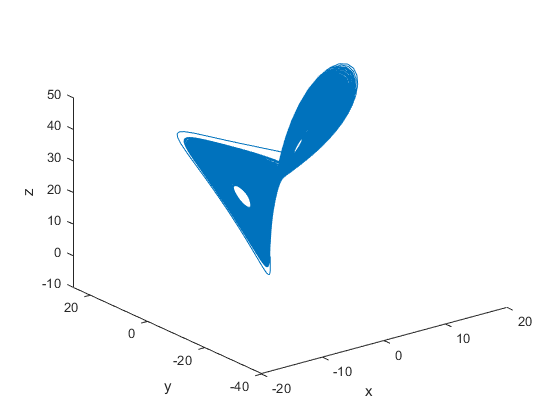

tspan = [0 2000]; %timespan
x0 = randn(3*N,1)*1e-1; %random starting positions
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0); %running the simulation

figure()
clf
plot3(X(:,1),X(:,2),X(:,3))
xlabel('x')
ylabel('y')
zlabel('z')

## Multiple oscilators

N = 4; %number of nodes
x0 = randn(3*N,1)*10;
f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N));r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


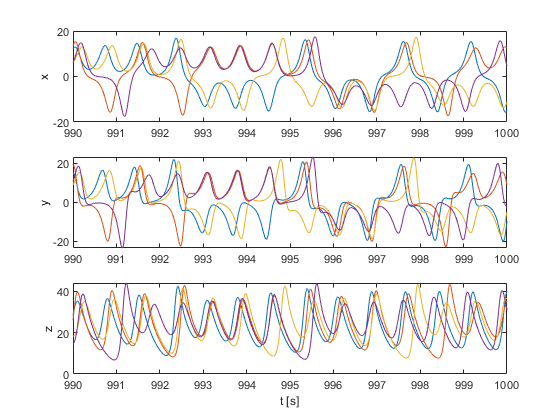

tspan = [0 1000]; %time span over which to simulate
x0 = randn(3*N,1)*10; %setting random starting positions
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0);

plot3Ddata(N,T,X,false,10) %as can be seen no synchronization occurs

N = 6; %number of nodes
m =[1 2;
    2 3;
    3 4;
    3 5;
    4 6;
    5 6;]; %connections
c_star = 6;
C = create_laplacian(N,m)*c_star; %creating the laplacian matrix
[v,d] = eig(C)

v =     0.4082    0.7018    0.5000         0   -0.2887    0.0864
    0.4082    0.3941   -0.5000         0    0.5774   -0.3077
    0.4082   -0.0864   -0.5000         0   -0.2887    0.7018
    0.4082   -0.3077    0.0000    0.7071   -0.2887   -0.3941
    0.4082   -0.3077    0.0000   -0.7071   -0.2887   -0.3941
    0.4082   -0.3941    0.5000         0    0.5774    0.3077


d =    -0.0000         0         0         0         0         0
         0    2.6307         0         0         0         0
         0         0   12.0000         0         0         0
         0         0         0   12.0000         0         0
         0         0         0         0   18.0000         0
         0         0         0         0         0   27.3693


m = [ 0 0 0 1 0 0;
      0 0 0 1 -1 0;
]

m =      0     0     0     1     0     0
     0     0     0     1    -1     0


m*C*pinv(m)

ans =    12.0000   -0.0000
   -0.0000   12.0000



f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)) - C*x(1:N); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N))-C*x(1:N);r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


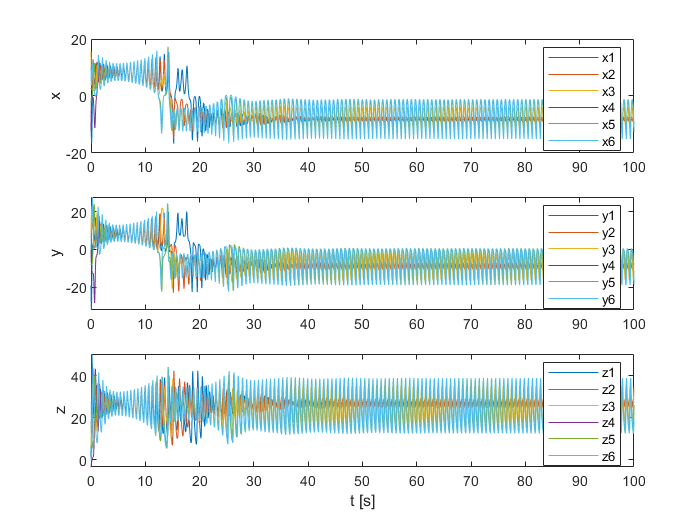

tspan = [0 100];
%x0 = randn(3*N,1)*10;
[T, X] = ode23(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0,odeset('RelTol',1e-6,'AbsTol',1e-6));
plot3Ddata(N,T,X,true,100)



N = 6; %number of nodes
m =[1 2;

    3 4;
    3 5;
    4 6;
    5 6;]; %connections
c_star = 20;
C = create_laplacian(N,m)*c_star; %creating the laplacian matrix

%creating the connectivity matrix D
m = [2 3]

m =      2     3


D = create_laplacian(N,m)*c_star

D =      0     0     0     0     0     0
     0    20   -20     0     0     0
     0   -20    20     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0





f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)) - C*x(1:N); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N) - D*x(N+1:2*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz   
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N))-C*x(1:N);r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N)-D*x(N+1:2*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


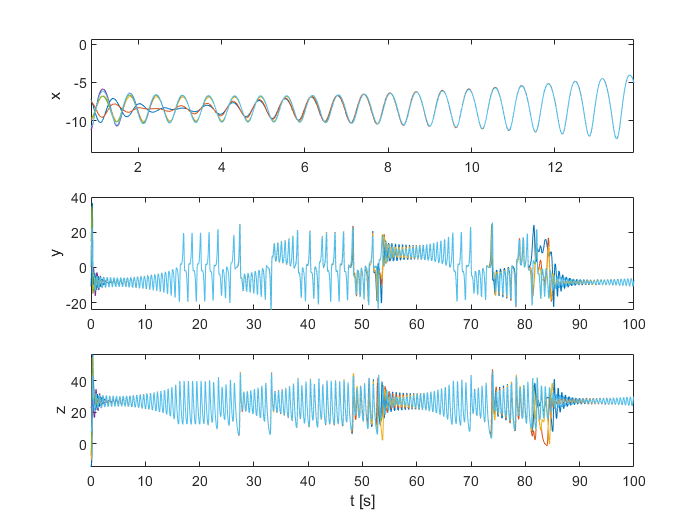

tspan = [0 100];
x0 = randn(3*N,1)*10;
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0);
plot3Ddata(N,T,X,false)

Six node circle

N = 6; %number of nodes
m =[1 2;
    2 3;
    3 4;
    4 5;
    5 6;
    6 1]; %connections
c_star = 8

c_star = 8

C = create_laplacian(N,m)*c_star; %creating the laplacian matrix

%creating the connectivity matrix D
m = []


m =

     []



D = create_laplacian(N,m)*c_star

D =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)) - C*x(1:N); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N) - D*x(N+1:2*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz   
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N))-C*x(1:N);r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N)-D*x(N+1:2*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


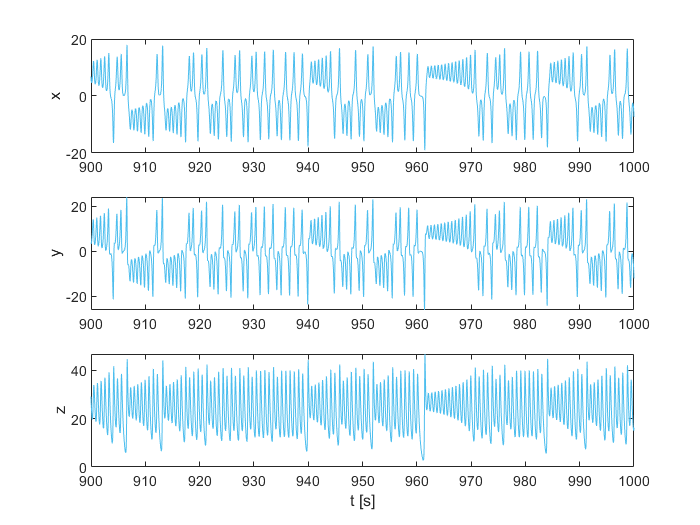

tspan = [0 1000];
x0 = randn(3*N,1)*10;
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0,odeset('RelTol',1e-6,'AbsTol',1e-6));

plot3Ddata(N,T,X,false,100)

ym = X(:,8);

Ts = mean(diff(T));                             % Sampling Interval
Fs = 1/Ts;                                          % Sampling Frequency
Fn = Fs/2;                                          % Nyquist Frequency
L = numel(T);                                   % Signal Length
FTvdp1 = fft(ym(:,1:2:size(ym,2)))/L;               % Fourier Trasnsform
Fv = linspace(0, 1, fix(L/2)+1)*Fn;                 % Frequency Vector
Iv = 1:numel(Fv);                                   % Index Vector

figure
clf
f = 1e2

f = 100

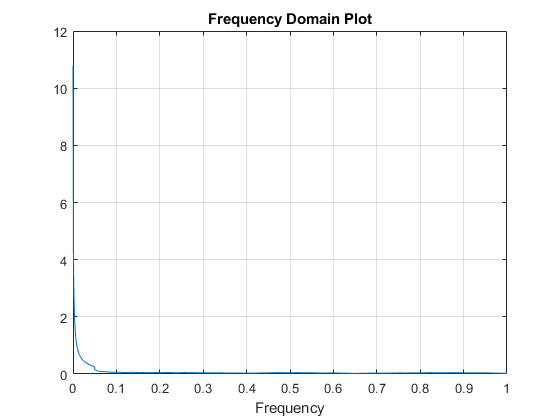

plot(Fv, smooth(abs(FTvdp1(Iv,:)),f))
grid
xlabel('Frequency')
title('Frequency Domain Plot')
xlim([0 1])